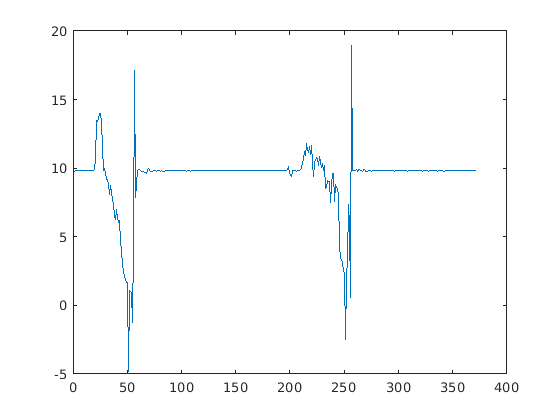

close all;
x = load("variable_a6.txt");
y = load("variable_b6.txt");
y = normalize(y, "range");

%x = x(40:550);
%y = y(40:550);

plot(x)

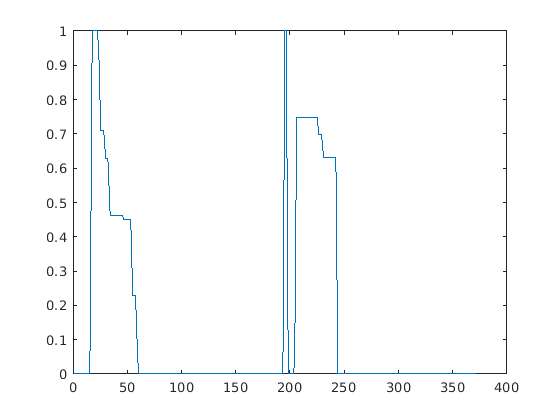

plot(y)


format long
b1 = x\y

b1 =    0.014662429853020


yCalc1 = b1*x;
scatter(x,y)
hold on
plot(x,yCalc1)
xlabel('acceleration')
ylabel('pwm_speeds')
grid on
X = [ones(length(x),1) x];
b = X\y

b =    0.184429778001142
  -0.004017239842368


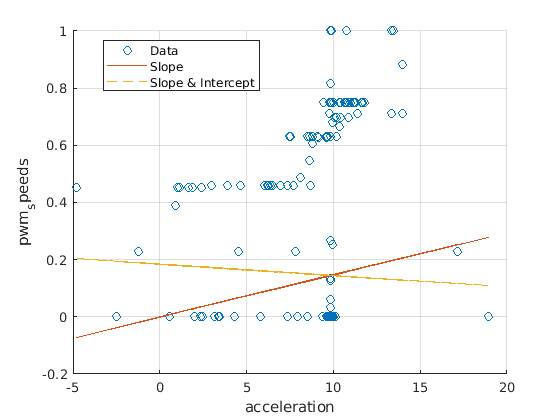

yCalc2 = X*b;
plot(x,yCalc2, '--')
legend('Data','Slope','Slope & Intercept','Location','best');
hold off


% normaliser pwm signal - Det har vi gjort nu :) 
% Tag højde for massen hvis vi hiver det ud i newton - Det gør de selv i
% blokken der styrer polynomiet som vi er ved at lave. 
% Fix tyngdekraften siden signalet ikke er 0 når den står stille i luften
% men 9.81.